# CIFAR-10 con capas densas

En este script vamos a tratar de resolver el problema de clasificar el objeto que hay en una imagen utilizando una red neuronal de capas densas. En concreto, vamos a probar primero usando las imágenes en blanco y negro y después a color por si hubiera algún cambio sustancial.

addpath(genpath('examples'));
SEED = 12345;
rng(SEED);

## Carga y normalización de los datos

[XTrain, YTrain, XTest, YTest] = ...
    loadCIFARData('examples/data/cifar-10');

XTrain = cast(XTrain, 'double') / 255;
XTest = cast(XTest, 'double') / 255;

## Obtención de las imágenes en blanco y negro

XTrainBW = zeros(32, 32, length(XTrain));
XTestBW = zeros(32, 32, length(XTest));
for i = 1:length(XTrainBW)
    XTrainBW(:, :, i) = rgb2gray(XTrain(:, :, :, i));
end
for i = 1:length(XTest)
    XTestBW(:, :, i) = rgb2gray(XTest(:, :, :, i));
end

## Subivisión de los conjunto de entrenamiento para validación

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
XValBW = XTrainBW(:, :, valInd);
YVal = YTrain(valInd);

XTrain = XTrain(:, :, :, trainInd);
XTrainBW = XTrainBW(:, :, trainInd);
YTrain = YTrain(trainInd);

## Creación de las redes

layersBW = [
    featureInputLayer(32 * 32, 'Name', 'input')
    
    fullyConnectedLayer(512, 'Name', 'dense1')
    reluLayer('Name', 'relu1')
    
    fullyConnectedLayer(1024, 'Name', 'dense2')
    reluLayer('Name', 'relu2')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

layers = [
    featureInputLayer(32 * 32 * 3, 'Name', 'input')
    
    fullyConnectedLayer(1024, 'Name', 'dense1')
    reluLayer('Name', 'relu1')
    
    fullyConnectedLayer(2048, 'Name', 'dense2')
    reluLayer('Name', 'relu2')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

## Adecuación de la entrada

Como sólo vamos a usar capas densas necesitamos que la entrada sea un array unidimensional.

XTrainBWIn = reshape(XTrainBW, 32 * 32, []).';
XValBWIn = reshape(XValBW, 32 * 32, []).';
XTestBWIn = reshape(XTestBW, 32 * 32, []).';

XTrainIn = reshape(XTrain, 32 * 32 * 3, []).';
XValIn = reshape(XVal, 32 * 32 * 3, []).';
XTestIn = reshape(XTest, 32 * 32 * 3, []).';

## Opciones de entrenamiento

miniBatchSize = 16;

optionsBW = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', .01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValBWIn, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', .01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValIn, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

## Entrenamiento

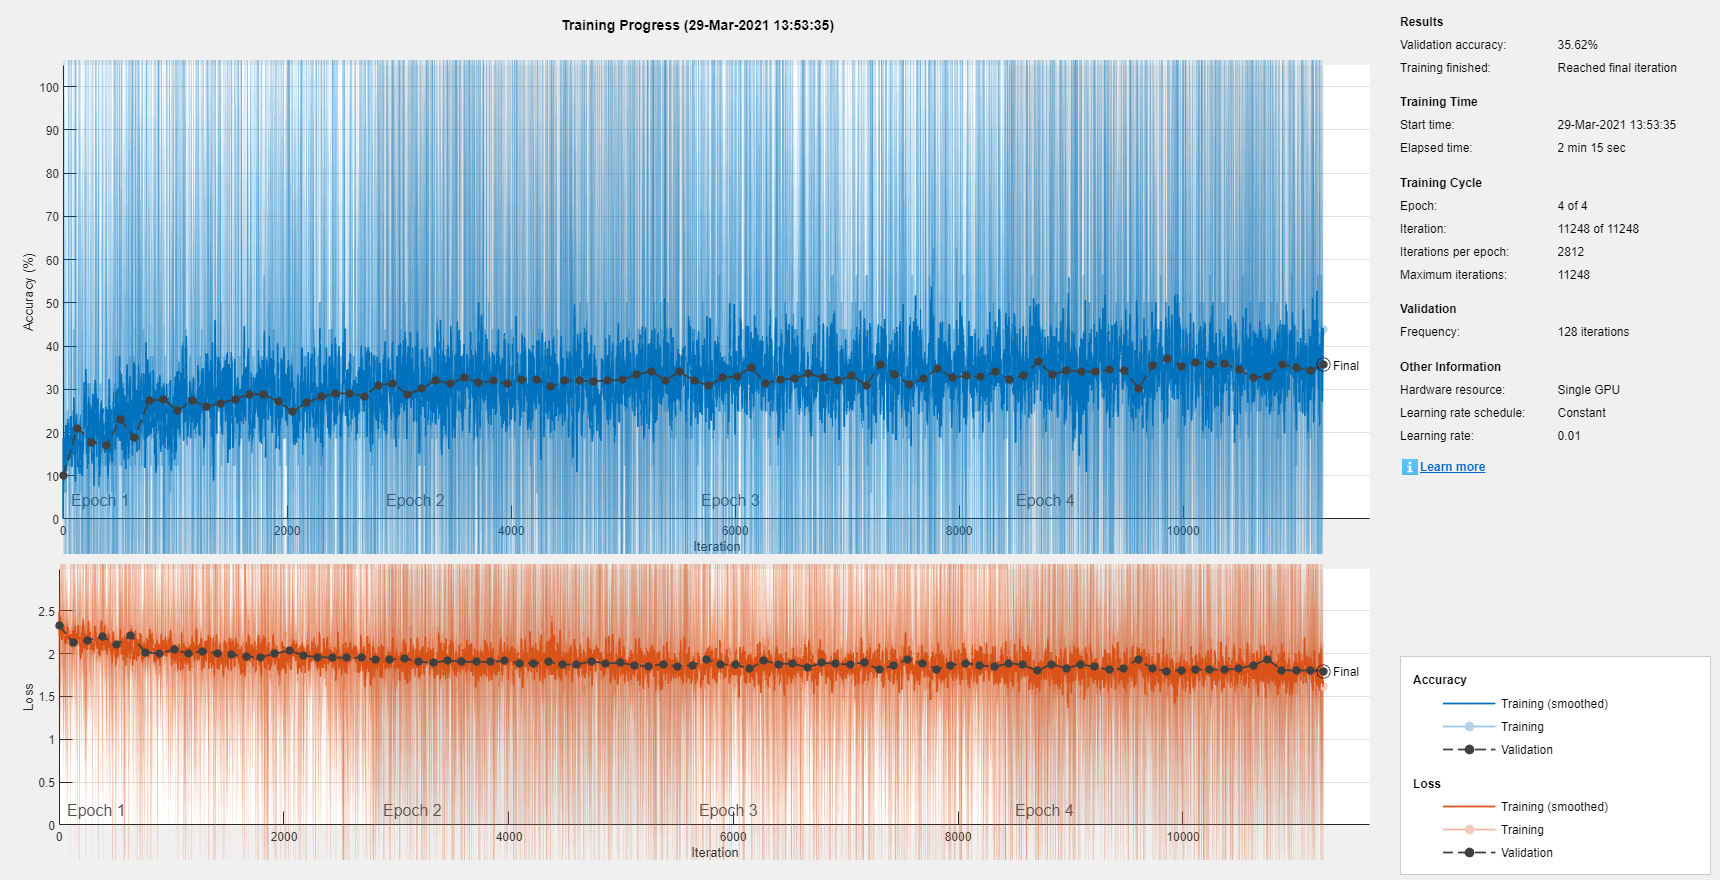

[netBW, infoBW] = trainNetwork(XTrainBWIn, YTrain, layersBW, optionsBW);

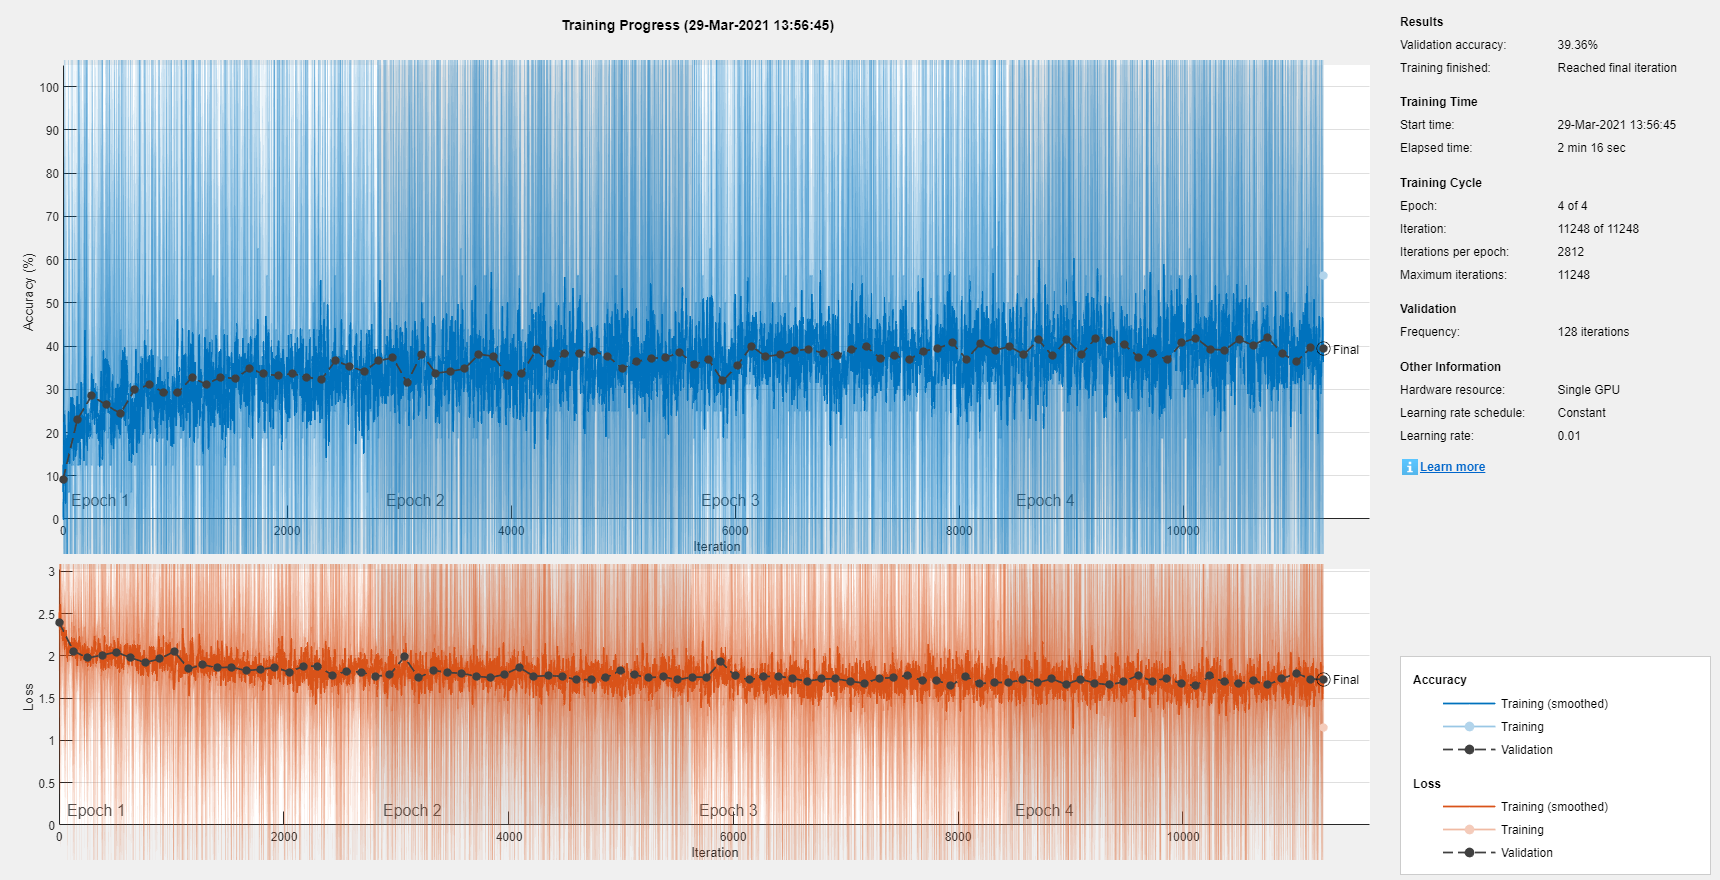

[net, info] = trainNetwork(XTrainIn, YTrain, layers, options);

save('examples/models/cifar10bwFC.mat', 'netBW');
save('examples/models/cifar10bwFCInfo.mat', 'infoBW');

save('examples/models/cifar10FC.mat', 'net');
save('examples/models/cifar10FCInfo.mat', 'info');

## Evaluación

categories = net.Layers(end).Classes;

probs = predict(netBW, XTestBWIn);
[~, YPred] = max(probs, [], 2);
YPred = categories(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("*Blanco y negro*\n");

*Blanco y negro*


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.3469


fprintf("****************\n");

****************


probs = predict(net, XTestIn);
[~, YPred] = max(probs, [], 2);
YPred = categories(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("****A  color****\n");

****A  color****


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.3860


fprintf("****************\n");

****************


## Resultados

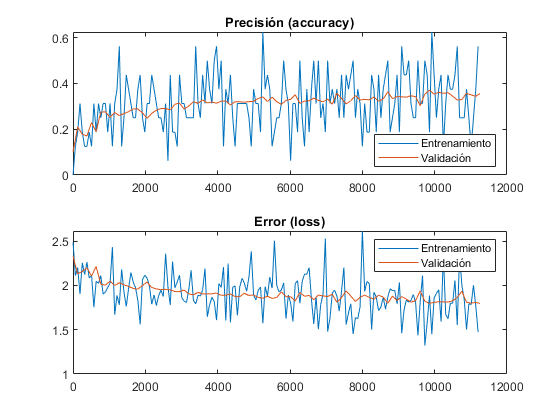

plotTraining(infoBW, miniBatchSize * 4);

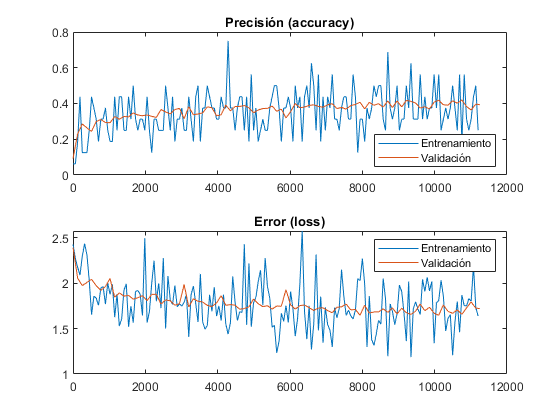

plotTraining(info, miniBatchSize * 4);

## Ejemplos

rng(SEED);
examplesBW = zeros(32, 32, 10);
examples = zeros(32, 32, 3, 10);
for i = 1:10
    filteredBW = XTrainBW(:, :, YTrain == categories(i));
    filtered = XTrain(:, :, :, YTrain == categories(i));
    index = floor(rand * size(filteredBW, 4)) + 1;
    examplesBW(:, :, i) = filteredBW(:, :, index);
    examples(:, :, :, i) = filtered(:, :, :, index);
end

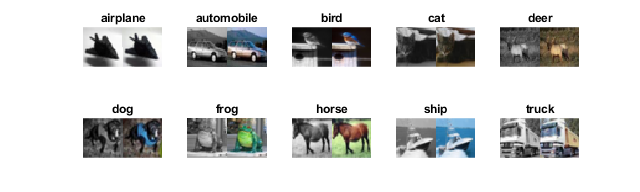

figure
position = get(gcf, 'Position');
set(gcf, 'Position',  [position(1:2) 64*10 32*6]);
for i = 1:10
    temp = zeros(32, 64, 3);
    temp(:, 1:32, :) = repmat(examplesBW(:, :, i), 1, 1, 3);
    temp(:, 33:64, :) = examples(:, :, :, i);
    subplot(2, 5, i);
    imshow(temp);
    title(categories(i));
end